**21AIE303 - Signal and Image Processing**

**Evaluation 1 – Assignment-1- 2D convolution**

Submitted by Jayanth M

CB.EN.U4AIE20024

clc
clear all
close all

- Write your own function in matlab/python to compute the following.

(i) Convolution with input containing single depth.

A=[22,15,1,3,60;
    42,5,38,39,7;
    28,9,4,66,79;
    0,82,45,12,17;
    99,14,72,51,3];
B=[0,0,1;0,0,0;0,0,0];
output= apply_filter(A,B,0,1)

output =      1     3    60
    38    39     7
     4    66    79


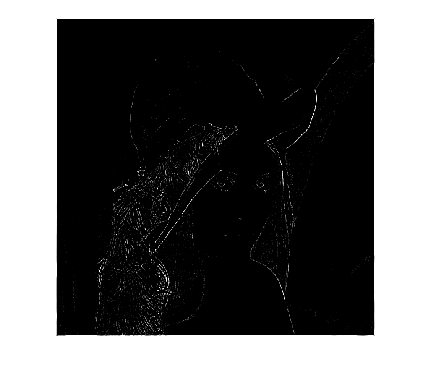

img=imread("Lena512.png");%Taken Lena Image for single depth / grayscale
img=im2double(img);
filter = [1,1,1;1,-9,1;1,1,1]; %Edge detection filter
final = apply_filter(img,filter,2,1);
imshow(final)

(ii) Convolution with input containing multiple depth.

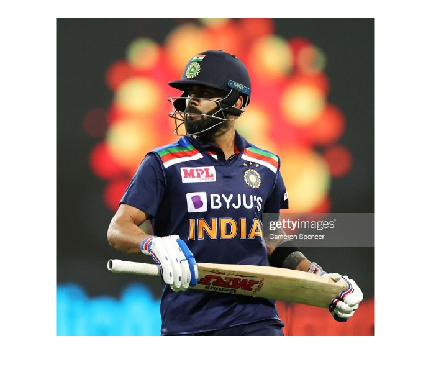

imgmult= imread("Virat.jpg");
imgmult=im2double(imgmult);
filtera = [1,1,1;1,-9,1;1,1,1];
filter3d(:,:,1)=filtera;
filter3d(:,:,2)=filtera;
filter3d(:,:,3)=filtera;
imshow(imgmult)

final=apply_mult_filter(imgmult,filter3d,2,1);

mult_filt = mult_filt(:,:,1) =

  Columns 1 through 499

   0.184313725490196   0.368627450980392   0.552941176470588   0.552941176470588   0.552941176470588   0.556862745098039   0.560784313725490   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.560784313725490   0.556862745098039   0.552941176470588   0.549019607843137   0.545098039215686   0.541176470588235   0.541176470588235   0.541176470588235   0.549019607843137   0.552941176470588   0.560784313725490   0.564705882352941   0.564705882352941   0.556862745098039   0.545098039215686   0.549019607843137   0.552941176470588   0.556862745098039   0.549019607843137   0.545098039215686   0.545098039215686   0.552941176470588   0.564705882352941   0.572549019607843   0.564705882352941   0.556862745098039   0.552941176470588   0.560784313725490   0.560784313725490   0.556862745098039   0.552941176470588   

mult_filt = mult_filt(:,:,1) =

  Columns 1 through 499

   0.184313725490196   0.368627450980392   0.552941176470588   0.552941176470588   0.552941176470588   0.556862745098039   0.560784313725490   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.560784313725490   0.556862745098039   0.552941176470588   0.549019607843137   0.545098039215686   0.541176470588235   0.541176470588235   0.541176470588235   0.549019607843137   0.552941176470588   0.560784313725490   0.564705882352941   0.564705882352941   0.556862745098039   0.545098039215686   0.549019607843137   0.552941176470588   0.556862745098039   0.549019607843137   0.545098039215686   0.545098039215686   0.552941176470588   0.564705882352941   0.572549019607843   0.564705882352941   0.556862745098039   0.552941176470588   0.560784313725490   0.560784313725490   0.556862745098039   0.552941176470588   

mult_filt = mult_filt(:,:,1) =

  Columns 1 through 499

   0.184313725490196   0.368627450980392   0.552941176470588   0.552941176470588   0.552941176470588   0.556862745098039   0.560784313725490   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.564705882352941   0.560784313725490   0.556862745098039   0.552941176470588   0.549019607843137   0.545098039215686   0.541176470588235   0.541176470588235   0.541176470588235   0.549019607843137   0.552941176470588   0.560784313725490   0.564705882352941   0.564705882352941   0.556862745098039   0.545098039215686   0.549019607843137   0.552941176470588   0.556862745098039   0.549019607843137   0.545098039215686   0.545098039215686   0.552941176470588   0.564705882352941   0.572549019607843   0.564705882352941   0.556862745098039   0.552941176470588   0.560784313725490   0.560784313725490   0.556862745098039   0.552941176470588   

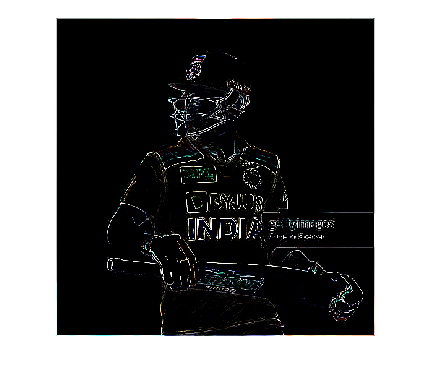

imshow(final)

(iii)Convolution with input containing multiple depth such that the output size equal to the input size.

% %pad = ((img_size(1)-1) * stride + filter_size - img_size(1))/2

2. Design and apply a filter to smoothen the grayscale image.

img1=imread("Virat.jpg");
img1=rgb2gray(img1);
img1=im2double(img1);
N=5

N =      5


kernal = ones(N,N)/N^2

kernal =    0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000
   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000
   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000
   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000
   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000   0.040000000000000


final_op=apply_filter(img1,kernal,2,1)

final_op =    0.070588235294118   0.094117647058824   0.117647058823529   0.117960784313725   0.118274509803922   0.118588235294118   0.118901960784314   0.119215686274510   0.119215686274510   0.119372549019608   0.119529411764706   0.119686274509804   0.120000000000000   0.120313725490196   0.120000000000000   0.119686274509804   0.119372549019608   0.118745098039216   0.118274509803922   0.118274509803922   0.118431372549020   0.118588235294118   0.118745098039216   0.118588235294118   0.118901960784314   0.119529411764706   0.119686274509804   0.119058823529412   0.118588235294118   0.118431372549020   0.117490196078431   0.117019607843137   0.117333333333333   0.117803921568627   0.117960784313725   0.118745098039216   0.119686274509804   0.120627450980392   0.120627450980392   0.120470588235294   0.120156862745098   0.119529411764706   0.118588235294118   0.118274509803922   0.117960784313725   0.117960784313725   0.118117647058824   0.118745098039216   0.119529411764706   0.1200

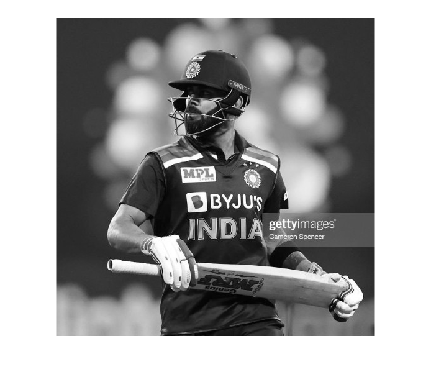

imshow(img1)

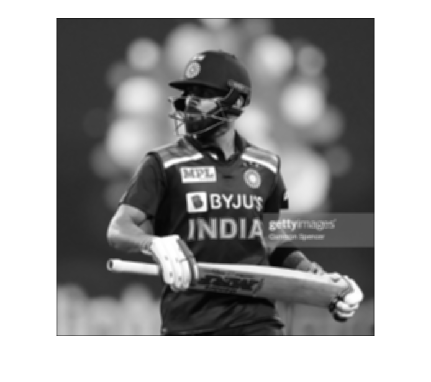

imshow(final_op)

3. Analyze the effect of filter size 3 x 3 and 4 x 4 on smoothening the grayscale image.

x=imread('Virat.jpg');
x=rgb2gray(x)

x = 512×512 uint8 matrix
   50   50   50   50   50   51   51   51   51   51   51   51   51   51   51   51   51   51   51   50   50   50   50   50   51   50   51   52   50   49   49   51   50   50   49   49   50   51   52   52   49   50   51   51   50   50   50   51   51   51
   50   50   50   50   50   51   51   51   51   51   51   51   51   51   51   51   50   50   50   50   50   50   51   51   50   50   51   52   51   49   49   51   50   50   50   50   51   52   52   52   50   51   51   51   50   49   50   51   51   51
   50   50   50   50   50   50   50   50   50   50   50   51   51   51   52   52   50   50   50   50   51   51   51   51   50   50   51   52   52   49   49   50   50   50   50   51   52   52   52   51   51   51   51   50   49   49   50   51   51   51
   50   50   50   50   50   50   50   50   49   49   50   50   51   51   52   52   50   50   50   50   50   50   51   51   50   49   51   52   52   50   49   50   49   49   50   51   52   52   51   50   52   51   51   50  

f=im2double(x);
%Filter chosen for smothening 
% Div by 16 averaging operation
filter=ones(4,4)/16

filter =    0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000
   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000
   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000
   0.062500000000000   0.062500000000000   0.062500000000000   0.062500000000000


filt1 = apply_filter(f,filter,2,1);
filter=ones(3,3)/9

filter =    0.111111111111111   0.111111111111111   0.111111111111111
   0.111111111111111   0.111111111111111   0.111111111111111
   0.111111111111111   0.111111111111111   0.111111111111111


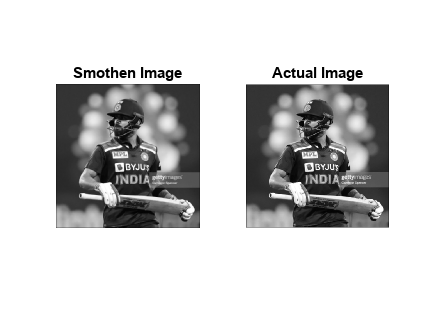

filt2 = apply_filter(f,filter,2,1);
figure;
subplot(1,2,1)
imshow(filt1)
title("Smothen Image")
subplot(1,2,2)
imshow(filt2)
title("Actual Image")

Observe the image to be more smothened/blurred in 4*4

function mult_filt = apply_mult_filter(image,filter,pad,stride)
    o_size = floor((size(image,1)+ 2*pad - size(filter,1))/ stride + 1) ;
    mult_filt = zeros(o_size,o_size,size(image,3));
    for i=1:size(image,3)
        mult_filt(:,:,i) = apply_filter(image(:,:,i),filter(:,:,i),pad,stride)
    end

end

function filtered = apply_filter(image,filter,pad,stride)
    image_size = size(image,1);
    image = [zeros(pad,image_size);image;zeros(pad,image_size)];
    image = [zeros(image_size+2*pad,pad),image,zeros(image_size+2*pad,pad)]; 
    filter_size = size(filter,1);
    o_size = floor((image_size + 2*pad - filter_size )/ stride + 1) ;
    filtered = zeros(o_size,o_size);

    for i = 1:o_size
        for j = 1:o_size
            r_start = (i-1)*stride+1 ;
            c_start = (j-1)*stride+1 ;
            filtered(i,j) = sum(sum(filter.*image(r_start:r_start+filter_size-1,c_start:c_start+filter_size-1)));
        end
    end
end
